# PSP ASA PSPSP PS1 Answers

#### Constants

R_E = 6378.1363; % [km]
mu_E = 398600.4415; % [km3 / s2]

### Q1

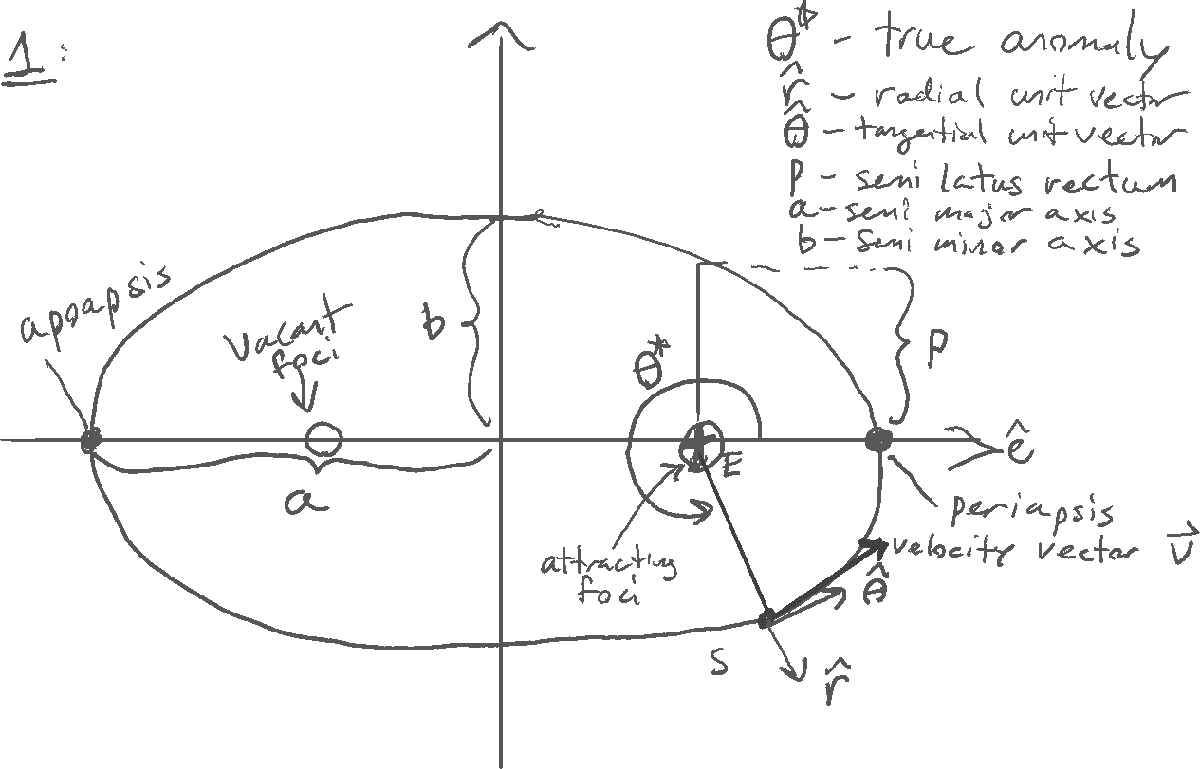

### Q2

% Given
alt = 560; % [km]

% Solution
a = alt + R_E; % Semimajor axis [km]
r = a; % Radius [km]
e = 0;
p = a * (1 - e ^ 2); % Semilatus rectum [km]
fprintf("Semimajor axis is %.5f km, radius is %.5f km, semilatus rectum is %.5f km.\n", a, r, p)

Semimajor axis is 6938.13630 km, radius is 6938.13630 km, semilatus rectum is 6938.13630 km.


a, r, p are all the same because the orbital radius is the same at every point in a circular orbit

specific_energy = -mu_E / (2 * a) % [km2 / s2]

specific_energy = -28.7253

v = sqrt(2 * (specific_energy + mu_E / r)) % [km / s]

v = 7.5796

% Check with formula for circular velocity
v_c = sqrt(mu_E / r) % [km / s]

v_c = 7.5796

Velocity (7.5796 km/s) from specific energy formula matches the result from the circular velocity formula so everything checks out.

### Q3

% Given
a = 12; % [R_E]
b = 10; % [R_E]

% Solution
e = sqrt(1 - (b / a) ^ 2) % []

e = 0.5528

p = a * (1 - e ^ 2) % [R_E]

p = 8.3333

r_a = p / (1 - e) % [R_E]

r_a = 18.6332

The triangle made by where the spacecraft is (end of semiminor axis), center of ellipse, and the Earth is a right triangle so Pythagorean theorem can be used to find the orbital radius. The distance between the center of the ellipse and the Earth is the semimajor axis subtracted by the apoapsis radius

r_bend = sqrt(b ^ 2 + (r_a - a) ^ 2) % [R_E]

r_bend = 12.0000

### Q4

% Given
e = 0.5;
r_1 = 5 * R_E; % [km]
v_1 = 5; % [km / s]
v_2 = 4; % [km / s]

% Solution
specific_energy = 1/2 * v_1 ^ 2 - mu_E / r_1 % [km2 / s2]

specific_energy = 0.0010

r_2 = mu_E / (1/2 * v_2 ^ 2 - specific_energy) / R_E % [R_E]

r_2 = 7.8129

Specific orbital energy remains constant throughout an orbit because it only depends on the gravitational parameter of the attracting body ($\mu$) and the semimajor axis of the orbit. More fundamentally, the specific energy is the sum of the specific kinetic energy ($\frac{1}{2}v^2$) and the specific gravitational potential energy ($-\frac{\mu}{r} = -\frac{GM}{r}$). This means that the specific energy is the specific mechanical energy which is conserved because gravity is a conservative force.

### Q5

I added some extra annotations because we will talk more about hyperbolic orbits soon for gravity assists

### 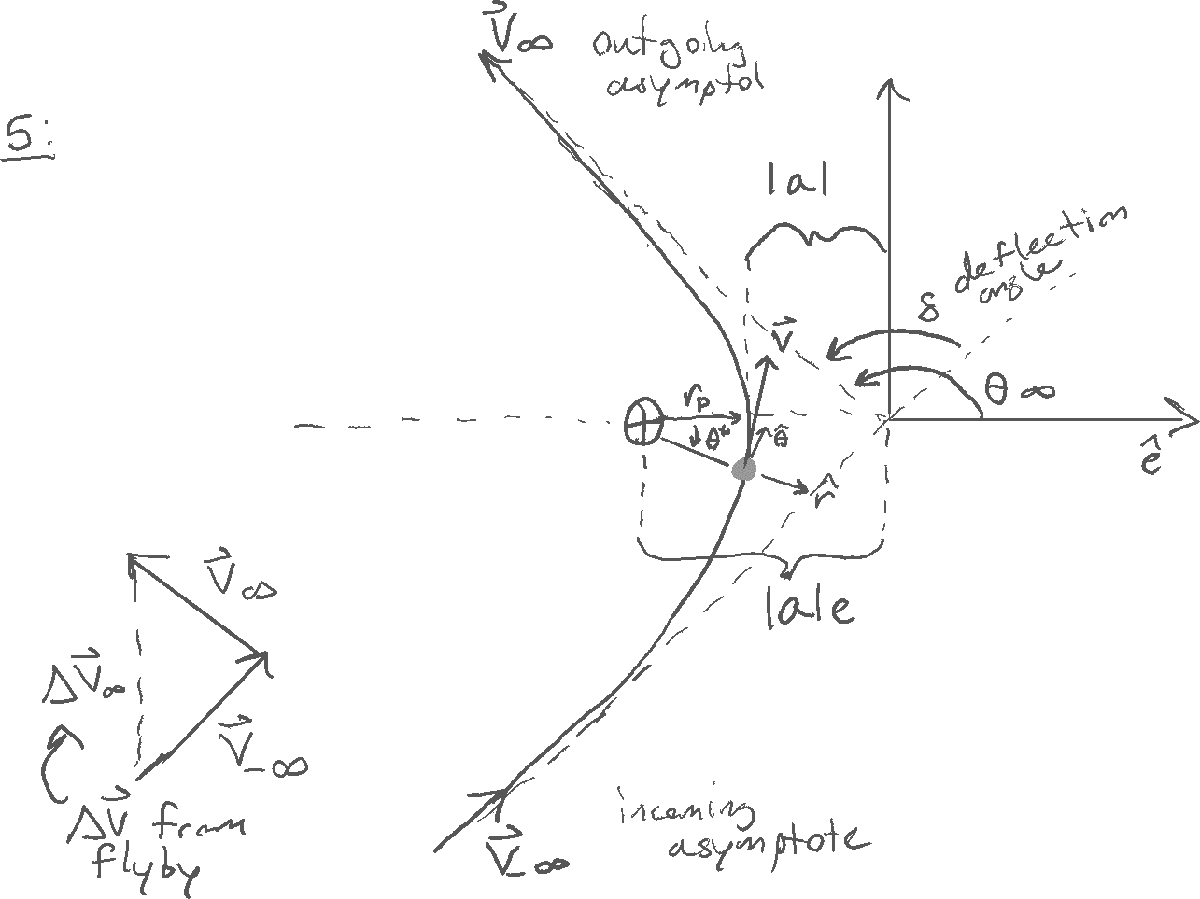

% Given
e = 1.2;
thetastar = deg2rad(-6);
specific_energy = +6.64; % [km2 / s2]

% Solution
a = -mu_E / (2 * specific_energy) / R_E % [R_E] semimajor axis

a = -4.7059

p = a * (1 - e ^ 2) % [R_E] semilatus rectum

p = 2.0706

r = p / (1 + e * cos(thetastar)) % [R_E] current radius

r = 0.9440

r_p = a * (1 - e) % [R_E] periapsis radius

r_p = 0.9412

hit_earth = r_p < 1 % Hits earth

r_a = -10.3531

hit_earth = logical
   1


The perigee radius is less than the radius of Earth so the spacecraft will hit the Earth (it is actually inside the Earth right now).